# 'surface' method usage example

#### Common setup for all examples

ex_setup

Setup complete


#### Start timer

tic

#### *Povlab* object

pl = povlab( povray_version,...
             povray_path, ...
             povray_out_dir);

#### Lights

pl.include_begin('lights');
    pl.light('location', [-10 -17 7],   'color', [2 2 2], 'shadowless', true);
    pl.light('location', [0 0 0],       'color', [4 4 4], 'shadowless', true);
    pl.light('location', [100 200 300], 'color', [1 1 1], 'shadowless', true);
pl.include_end();

#### Environment

pl.include_begin('environment');
    pl.raw(['sky_sphere{ pigment{ gradient <0,0,1> '...
                      'color_map{ [0   color rgb<0.0,0.0, 0.0> ] '...
                                 '[0.4 color rgb<0.01, 0.01, 0.01>   ] '...
                                 '[0.9 color rgb<0.05, 0.05, 0.05>   ]  '...
                                 '[1.0 color rgb<0.1,0.1,0.1>     ]} '...
                      'scale 1  }}']);
    pl.global_settings("assumed_gamma 1");
pl.include_end();


#### Scene 1

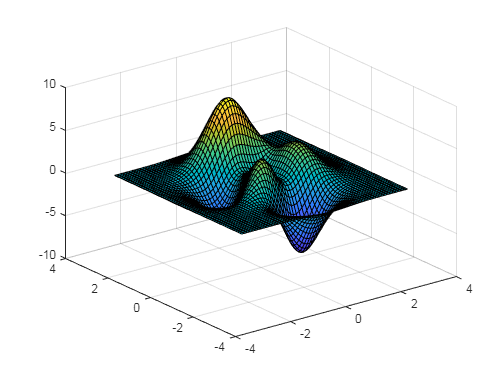

pl.scene_begin('scene_file', 'surface.pov', 'image_file', 'surface.png');
    pl.include("lights");
    pl.include("environment");    
    pl.include("textures");
    pl.include("glass");
    pl.include("metals");
       
    pl.camera('angle', 35, 'location', [-10 -10 6], 'look_at', [0 0 0], 'type', 'perspective');
    size = 60;
    [X,Y,Z] = peaks(size);
    s = surf(X,Y,Z);

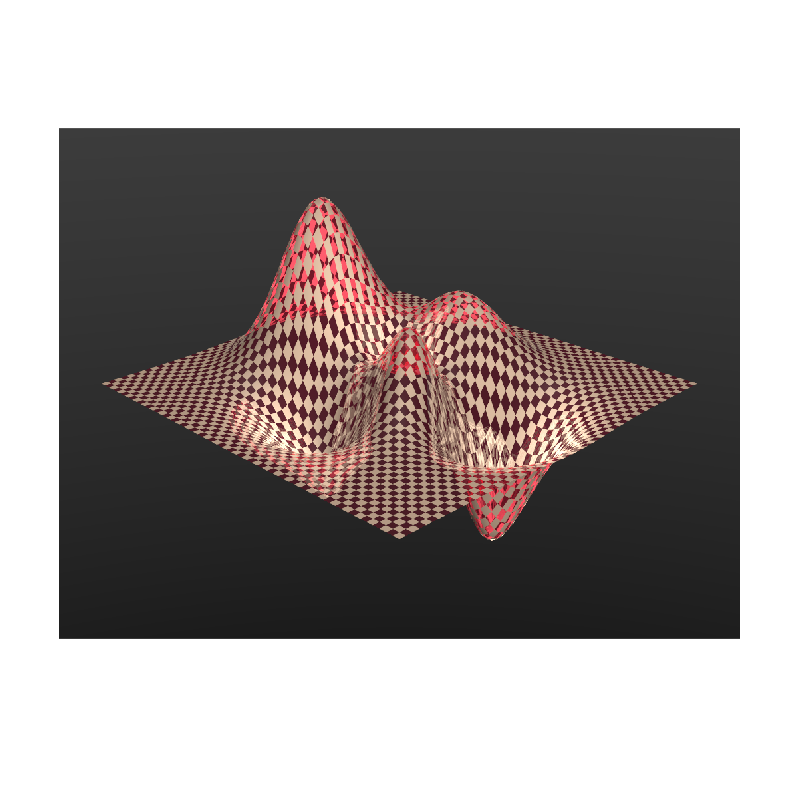


    pl.surface('surface', s, 'colormap', 'turbo', 'scale', [1, 1, 3/10], 'texture_odd', 'Gold_Nugget', 'texture_even', 'T_Ruby_Glass');
pl.scene_end();

% Rendering and display
image = pl.render();
imshow(image);

#### Scene 2

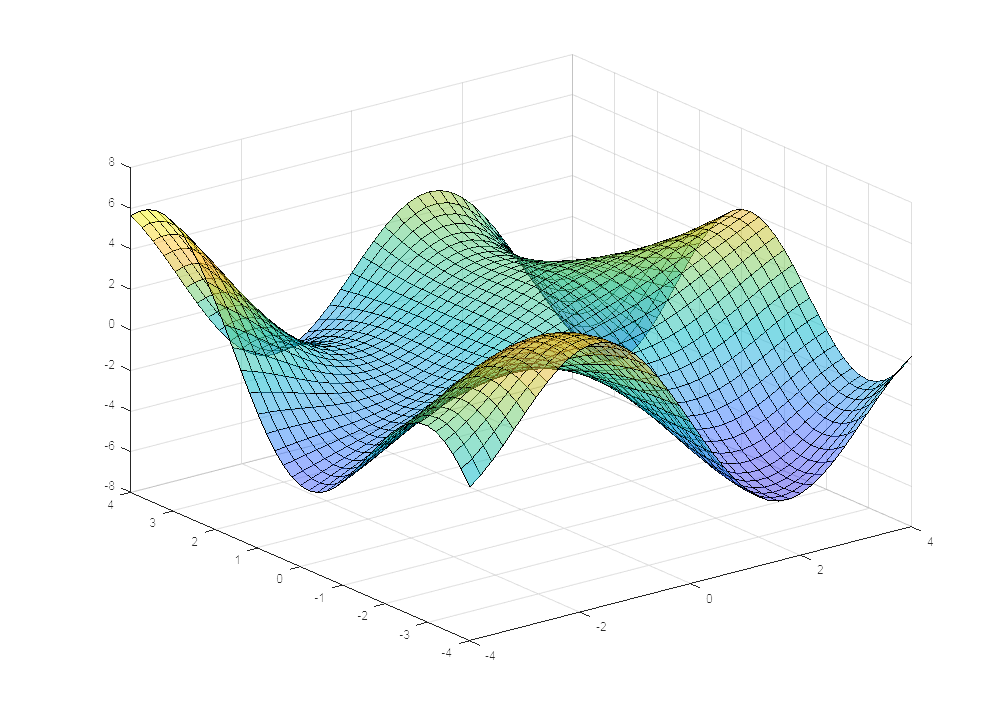

pl.scene_begin('scene_file', 'surface.pov', 'image_file', 'surface.png');
    pl.include("lights");
    pl.include("environment");    
    pl.include("textures");
    pl.include("glass");
    pl.include("metals");
       
    pl.camera('angle', 35, 'location', [-12 -12 8], 'look_at', [0 0 0], 'type', 'perspective');
    [X,Y] = meshgrid(-4:.2:4);
    Z = Y.*sin(X) + X.*cos(Y);
    s = surf(X,Y,Z,'FaceAlpha',0.5);

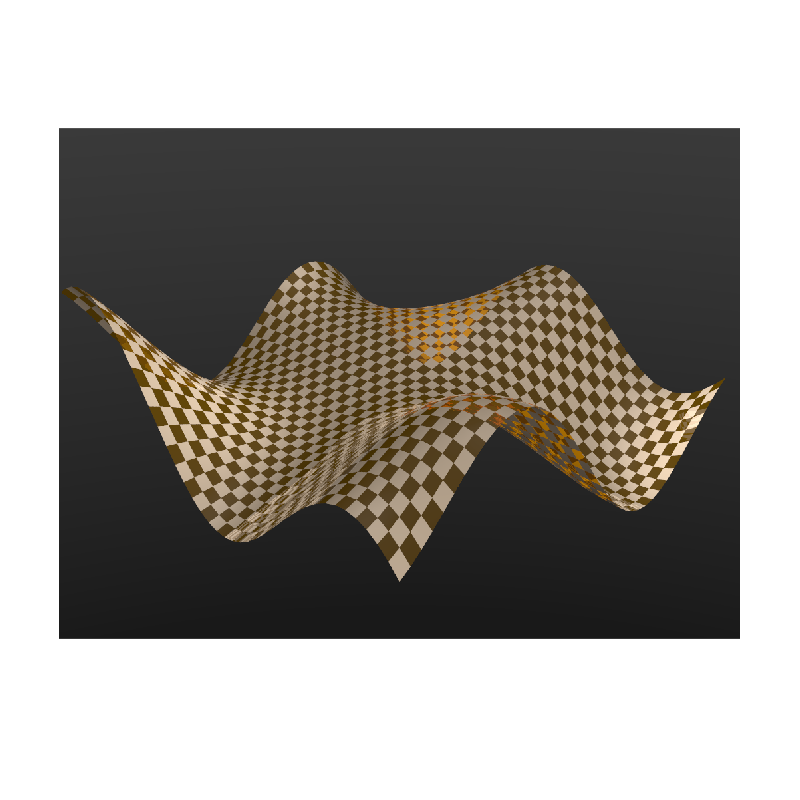

    pl.surface('surface', s, 'colormap', 'turbo', 'scale', [1, 1, 3/10], 'texture_odd', 'Bright_Bronze', 'texture_even', 'Orange_Glass');

pl.scene_end();

% Rendering and display
image = pl.render();
imshow(image);

#### Scene 3

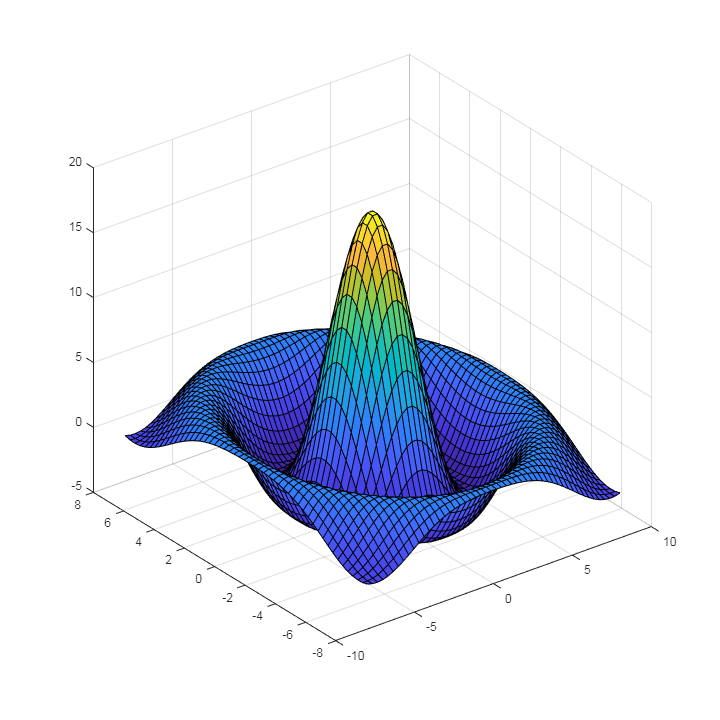

pl.scene_begin('scene_file', 'surface.pov', 'image_file', 'surface.png');
    pl.include("lights");
    pl.include("environment");    
    pl.include("textures");
    pl.include("glass");
    pl.include("metals");
       
    pl.camera('angle', 35, 'location', [-25 -25 10], 'look_at', [0 0 0], 'type', 'perspective');
    t = linspace (-8, 8, 50);
    [x, y] = meshgrid (t, t);
    r = sqrt (x .^ 2 + y .^ 2) + eps;
    z = 18 * sin (r) ./ r;
    s = surf(x,y,z);

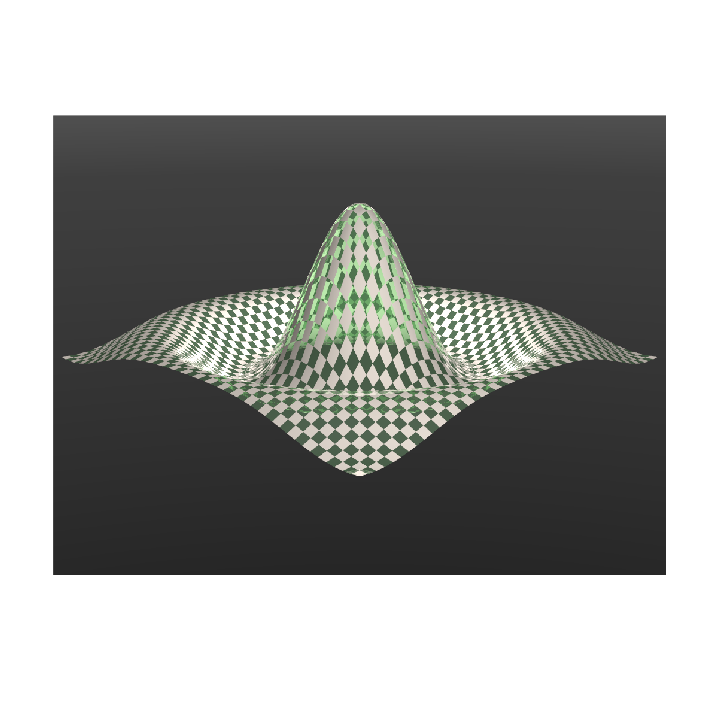

    pl.surface('surface', s, 'colormap', 'turbo', 'scale', [1, 1, 3/10], 'texture_odd', 'Aluminum', 'texture_even', 'T_Winebottle_Glass');

pl.scene_end();

% Rendering and display
image = pl.render();
imshow(image);

#### Display elapsed time

toc

Elapsed time is 38.144676 seconds.
